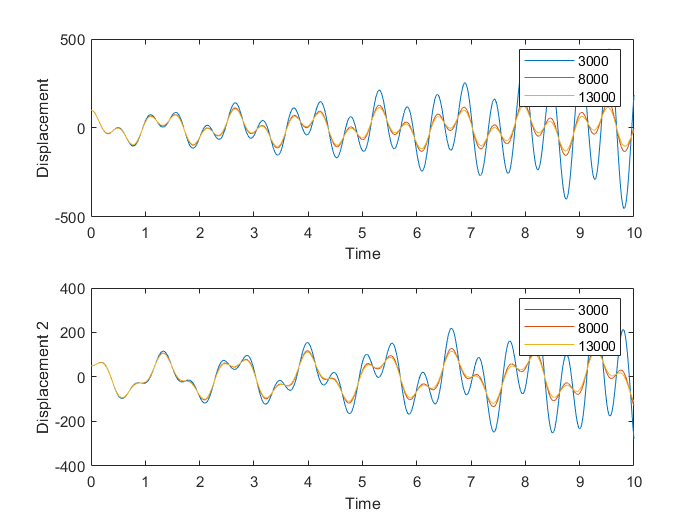

clear

x1_0 = 100;
x2_0 = 50;
x1_prime_0 = 0;
x2_prime_0 = 0;
m1 = 0.0917;
m2 = 0.0765;
k1 = 4.66;
k2 = k1;
A = [0 1 0 0; (-k1 - k2)/m1 0 k2/m1 0; 0 0 0 1; k2/m2 0 -k2/m2 0];
results_vector = [x1_0, x1_prime_0, x2_0, x2_prime_0];
figure

for N = 3000:5000:15000
    yi = results_vector;
    delta_t = 10/N;
    time = 0:delta_t:10;
    matrix = zeros(4, N);
    matrix(:,1) = [100;0;50;0];
    for i = 1:N
        y_prime = yi*A;
        yii = yi + (delta_t * y_prime);
        matrix(:,i+1) = yii;
        yi = yii;
    end

    subplot(2,1,1)
    plot(time, matrix(1,:), 'DisplayName', num2str(N))
    legend show
    ylabel('Displacement')
    xlabel('Time')
    xlim([0 10])
    hold on

    subplot(2,1,2)
    plot(time, matrix(3,:), 'DisplayName', num2str(N))
    legend show
    ylabel('Displacement 2')
    xlabel('Time')
    xlim([0 10])
    hold on
end


eig(A)

ans =    0.0000 +11.8542i
   0.0000 -11.8542i
   0.0000 + 4.6935i
   0.0000 - 4.6935i
